%% Treino e exportacao da RNA MLP para VHDL
% Aplicacao: classificacao de arroz tipo 1 x arroz tipo 3/4.

clear; clc; close all;

%% 1. Configuracoes
datasetPath = 'dataset_qualidade_gray';
inputSize = [20 20 1];
numInputs = prod(inputSize);

DATA_WIDTH = 20;
FRACT_BITS = 12;
scaleFactor = 2^FRACT_BITS;

hiddenLayerSize = 4;

vhdlProjectPath = "C:\intelFPGA_lite\17.1\TCC final RNA01";

if isfolder(vhdlProjectPath)
    exportDir = char(vhdlProjectPath);
else
    warning('Pasta VHDL nao encontrada: %s. Gerando arquivos na pasta atual do MATLAB.', char(vhdlProjectPath));
    exportDir = pwd;
end

paramPkgFile = fullfile(exportDir, 'rna_arroz_param_pkg.vhd');
testVectorPkgFile = fullfile(exportDir, 'rna_arroz_test_vector_pkg.vhd');
modelsimDoFile = fullfile(exportDir, 'compile_rna_auto.do');

% Ajuste estes nomes se os arquivos no projeto tiverem outros nomes.
rnaVhdlFile = 'RNA finalizada.vhd';
testbenchVhdlFile = 'tb_rna_mlp.vhd';
testbenchEntity = 'tb_rna_mlp';

% Opcional: imagem usada no testbench VHDL.
testImagePath = "C:\Users\heric\MATLAB\Projects\untitled\dataset_qualidade_gray\arroz_tipo3_4\IMG_20260915_195652522_tipo34_091.png";

%% 2. Carregar dados
if ~exist(datasetPath, 'dir')
    error('Pasta de dataset nao encontrada. Rode o script de extracao primeiro.');
end

imds = imageDatastore(datasetPath, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

classNames = categories(imds.Labels);
numClasses = numel(classNames);

fprintf('Classes detectadas: %d (%s)\n', numClasses, strjoin(classNames, ', '));

Classes detectadas: 2 (arroz_tipo1, arroz_tipo3_4)


if numClasses ~= 2
    warning('O VHDL foi parametrizado para classificacao binaria; confira N_OUTPUTS_C se usar outra quantidade de classes.');
end

TEST_FRACTION = 0.30;
NUM_SPLIT_TRIES = 50000;

rng(7);

[imdsTrain, imdsTest, splitInfo] = split_by_source_photo( ...
    imds, TEST_FRACTION, NUM_SPLIT_TRIES);

fprintf('\n=== DIVISAO DO DATASET POR FOTOGRAFIA ===\n');


=== DIVISAO DO DATASET POR FOTOGRAFIA ===



fprintf('Fotografias de origem: %d\n', splitInfo.numSources);

Fotografias de origem: 45


fprintf('Fotografias de treinamento: %d\n', splitInfo.numTrainSources);

Fotografias de treinamento: 31


fprintf('Fotografias de teste: %d\n\n', splitInfo.numTestSources);

Fotografias de teste: 14




fprintf('Amostras de treinamento: %d (%.2f%%)\n', ...
    numel(imdsTrain.Files), ...
    100*numel(imdsTrain.Files)/numel(imds.Files));

Amostras de treinamento: 7106 (70.00%)



fprintf('Amostras de teste: %d (%.2f%%)\n\n', ...
    numel(imdsTest.Files), ...
    100*numel(imdsTest.Files)/numel(imds.Files));

Amostras de teste: 3045 (30.00%)




% Mostra a distribuição das classes
classNamesSplit = string(categories(imds.Labels));

for c = 1:numel(classNamesSplit)

    nomeClasse = classNamesSplit(c);

    totalClasse = sum(string(imds.Labels) == nomeClasse);
    treinoClasse = sum(string(imdsTrain.Labels) == nomeClasse);
    testeClasse = sum(string(imdsTest.Labels) == nomeClasse);

    fprintf('%s:\n', nomeClasse);
    fprintf('  Total:  %d\n', totalClasse);
    fprintf('  Treino: %d (%.2f%%)\n', ...
        treinoClasse, 100*treinoClasse/totalClasse);
    fprintf('  Teste:  %d (%.2f%%)\n\n', ...
        testeClasse, 100*testeClasse/totalClasse);
end

arroz_tipo1:


  Total:  5084


  Treino: 3561 (70.04%)


  Teste:  1523 (29.96%)



arroz_tipo3_4:


  Total:  5067


  Treino: 3545 (69.96%)


  Teste:  1522 (30.04%)




fprintf('Fotografias reservadas exclusivamente para TESTE:\n');

Fotografias reservadas exclusivamente para TESTE:



for k = 1:numel(splitInfo.testSources)
    fprintf('  %s\n', splitInfo.testSources(k));
end

  IMG_20260911_171807132
  IMG_20260915_201751972
  IMG_20260913_205852581
  IMG_20260915_195652522
  IMG_20260920_154458857
  IMG_20260913_160348512
  IMG_20260913_211215027
  IMG_20260920_164900826
  IMG_20260913_155714564
  IMG_20260920_153555016
  IMG_20260913_194140081
  IMG_20260913_155132563
  IMG_20260920_083233216
  IMG_20260913_200919788



fprintf('\n');

% Guarda a divisão utilizada para reprodução posterior
save('split_por_fotografia.mat', 'splitInfo');

% Carrega os dados normalmente
XTrain = read_images_as_columns(imdsTrain, numInputs);
YTrain = full(ind2vec(grp2idx(imdsTrain.Labels)'));

XTest = read_images_as_columns(imdsTest, numInputs);
YTest = full(ind2vec(grp2idx(imdsTest.Labels)'));

%% 3. Treinar rede
fprintf('Treinando a rede neural...\n');

Treinando a rede neural...


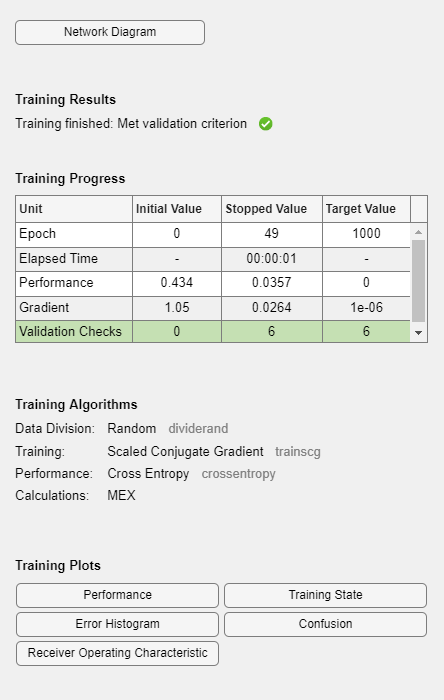


rng(7);

net = patternnet(hiddenLayerSize);

% Mantem o comportamento que normalmente da boa acuracia no patternnet:
% removeconstantrows + mapminmax na entrada, tansig na camada oculta e
% softmax na saida. O processamento da entrada sera dobrado nos pesos
% exportados da primeira camada, entao o VHDL continua recebendo os 400
% pixels crus em Q7.12.
net.inputs{1}.processFcns = {'removeconstantrows', 'mapminmax'};
net.layers{1}.transferFcn = 'tansig';
net.layers{2}.transferFcn = 'softmax';

net.trainParam.epochs = 1000;
net.trainParam.showWindow = true;

[net, tr] = train(net, XTrain, YTrain);


YPred = net(XTest);
[~, predIdx] = max(YPred, [], 1);
[~, trueIdx] = max(YTest, [], 1);
acc = mean(predIdx == trueIdx);

fprintf('Acuracia no teste: %.2f%%\n', 100 * acc);

Acuracia no teste: 96.98%


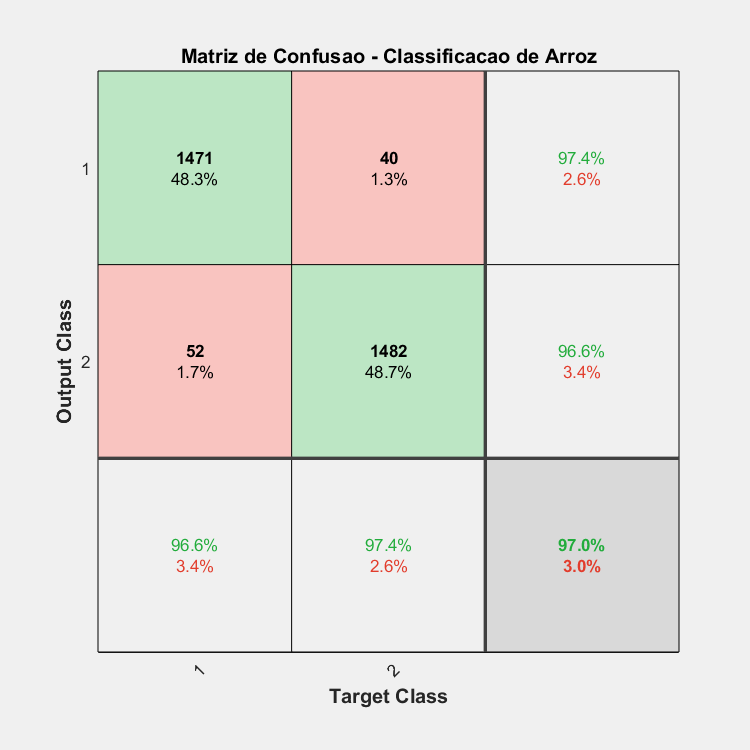


figure;
plotconfusion(YTest, YPred);
title('Matriz de Confusao - Classificacao de Arroz');


%% 4. Dobrar o processamento de entrada nos pesos da primeira camada e quantizar
[W1_eff, b1_eff] = fold_input_processing( ...
    net.IW{1}, ...
    net.b{1}, ...
    net.inputs{1}.processFcns, ...
    net.inputs{1}.processSettings, ...
    numInputs);

W1_raw = W1_eff * scaleFactor;
b1_raw = b1_eff * scaleFactor;
W2_raw = net.LW{2,1} * scaleFactor;
b2_raw = net.b{2} * scaleFactor;

[W1_fix, satW1] = quantize_signed(W1_raw, DATA_WIDTH);
[b1_fix, satB1] = quantize_signed(b1_raw, DATA_WIDTH);
[W2_fix, satW2] = quantize_signed(W2_raw, DATA_WIDTH);
[b2_fix, satB2] = quantize_signed(b2_raw, DATA_WIDTH);

totalSat = satW1 + satB1 + satW2 + satB2;
if totalSat > 0
    warning('%d parametros saturaram na quantizacao para signed(%d bits).', totalSat, DATA_WIDTH);
    report_saturation('W1', W1_raw, DATA_WIDTH, scaleFactor);
    report_saturation('b1', b1_raw, DATA_WIDTH, scaleFactor);
    report_saturation('W2', W2_raw, DATA_WIDTH, scaleFactor);
    report_saturation('b2', b2_raw, DATA_WIDTH, scaleFactor);
end

%% 5. Exportar pacote VHDL de parametros
write_param_pkg(paramPkgFile, W1_fix, b1_fix, W2_fix, b2_fix, classNames, DATA_WIDTH, FRACT_BITS);
fprintf('Pacote VHDL gerado: %s\n', paramPkgFile);

Pacote VHDL gerado: C:\intelFPGA_lite\17.1\TCC final RNA01\rna_arroz_param_pkg.vhd



%% 6. Exportar vetor de teste opcional
if strlength(testImagePath) > 0 && isfile(testImagePath)
    write_test_vector_pkg(testVectorPkgFile, testImagePath, numInputs, DATA_WIDTH, FRACT_BITS);
    fprintf('Vetor de teste VHDL gerado: %s\n', testVectorPkgFile);
    diagnose_test_image_fixed_point(testImagePath, net, W1_fix, b1_fix, W2_fix, b2_fix, classNames, DATA_WIDTH, FRACT_BITS);
else
    fprintf('Vetor de teste nao gerado; ajuste testImagePath se quiser usar o testbench.\n');
end

Vetor de teste VHDL gerado: C:\intelFPGA_lite\17.1\TCC final RNA01\rna_arroz_test_vector_pkg.vhd



Diagnóstico do vetor de teste:
  Imagem: IMG_20260915_195652522_tipo34_091.png
  MATLAB float -> classe: arroz_tipo3_4, saídas: 0.017279  0.982721  
  VHDL fixo    -> classe: arroz_tipo3_4, logits fixos: -5810  10488  (em real Q12: -1.418457  2.560547  )



%% 7. Gerar script opcional de compilacao do ModelSim
write_modelsim_do(modelsimDoFile, rnaVhdlFile, testbenchVhdlFile, testbenchEntity);
fprintf('Script ModelSim gerado: %s\n', modelsimDoFile);

Script ModelSim gerado: C:\intelFPGA_lite\17.1\TCC final RNA01\compile_rna_auto.do



%% Funcoes locais

function X = read_images_as_columns(imds, numInputs)
    X = zeros(numInputs, numel(imds.Files));

    for k = 1:numel(imds.Files)
        img = readimage(imds, k);
        if size(img, 3) == 3
            img = rgb2gray(img);
        end

        img = im2double(img);
        if numel(img) ~= numInputs
            error('Imagem %s tem %d pixels, mas a rede espera %d.', imds.Files{k}, numel(img), numInputs);
        end

        % Mesma ordem usada pelo VHDL/testbench: reshape column-major.
        X(:, k) = reshape(img, [], 1);
    end
end

function [q, saturatedCount] = quantize_signed(values, dataWidth)
    minVal = -2^(dataWidth - 1);
    maxVal = 2^(dataWidth - 1) - 1;

    rounded = round(values);
    saturatedCount = nnz(rounded < minVal | rounded > maxVal);
    q = min(max(rounded, minVal), maxVal);
end

function [W_eff, b_eff] = fold_input_processing(W, b, processFcns, processSettings, numInputs)
    keep = (1:numInputs).';
    gain = ones(numInputs, 1);
    offset = zeros(numInputs, 1);

    for p = 1:numel(processFcns)
        settings = processSettings{p};

        switch processFcns{p}
            case 'removeconstantrows'
                if isfield(settings, 'keep')
                    keep = keep(settings.keep(:));
                    gain = gain(settings.keep(:));
                    offset = offset(settings.keep(:));
                end

            case 'mapminmax'
                mapGain = settings.gain(:);
                xoffset = settings.xoffset(:);
                ymin = settings.ymin;
                if ~isscalar(ymin)
                    ymin = ymin(:);
                end

                gain = gain .* mapGain;
                offset = (offset - xoffset) .* mapGain + ymin;

            otherwise
                error('Processamento de entrada nao suportado para exportacao VHDL: %s', processFcns{p});
        end
    end

    if size(W, 2) ~= numel(keep)
        error('Dimensao inesperada: W tem %d colunas, mas o processamento de entrada gerou %d sinais.', size(W, 2), numel(keep));
    end

    W_eff = zeros(size(W, 1), numInputs);
    for k = 1:numel(keep)
        W_eff(:, keep(k)) = W(:, k) .* gain(k);
    end

    b_eff = b + W * offset;
end

function report_saturation(name, rawValues, dataWidth, scaleFactor)
    minVal = -2^(dataWidth - 1);
    maxVal = 2^(dataWidth - 1) - 1;
    rounded = round(rawValues);
    mask = rounded < minVal | rounded > maxVal;

    if ~any(mask, 'all')
        return;
    end

    [rows, cols] = find(mask);
    fprintf('\nParametros saturados em %s:\n', name);
    for k = 1:numel(rows)
        rawFixed = rounded(rows(k), cols(k));
        rawReal = rawValues(rows(k), cols(k)) / scaleFactor;

        if rawFixed < minVal
            clippedFixed = minVal;
        else
            clippedFixed = maxVal;
        end

        fprintf('  %s(%d,%d): real %.8f, fix bruto %d, fix saturado %d\n', ...
            name, rows(k), cols(k), rawReal, rawFixed, clippedFixed);
    end
    fprintf('\n');
end

function diagnose_test_image_fixed_point(imagePath, net, W1, b1, W2, b2, classNames, dataWidth, fractBits)
    scaleFactor = 2^fractBits;

    img = imread(imagePath);
    if size(img, 3) == 3
        img = rgb2gray(img);
    end

    xFloat = reshape(im2double(img), [], 1);
    yFloat = net(xFloat);
    [~, matlabClass] = max(yFloat, [], 1);

    xFix = min(max(round(xFloat * scaleFactor), 0), 2^(dataWidth - 1) - 1);
    [hiddenFix, hiddenPreAct] = fixed_layer_forward(xFix, W1, b1, dataWidth, fractBits, 'tansig');
    [outFix, outPreAct] = fixed_layer_forward(hiddenFix, W2, b2, dataWidth, fractBits, 'linear');
    [~, fixedClass] = max(outFix, [], 1);

    fprintf('\nDiagnóstico do vetor de teste:\n');
    [~, nomeImagem, extensao] = fileparts(imagePath);
    fprintf('  Imagem: %s%s\n', nomeImagem, extensao);

    fprintf('  MATLAB float -> classe: %s, saídas: ', ...
    classNames{matlabClass});
    fprintf('%.6f  ', yFloat);
    fprintf('\n');

    fprintf('  VHDL fixo    -> classe: %s, logits fixos: ', ...
    classNames{fixedClass});
    fprintf('%d  ', outFix);

    fprintf('(em real Q%d: ', fractBits);
    fprintf('%.6f  ', outFix / scaleFactor);
    fprintf(')\n');

end

function [yFix, preActSat] = fixed_layer_forward(xFix, WFix, bFix, dataWidth, fractBits, activation)
    numNeurons = size(WFix, 1);
    yFix = zeros(numNeurons, 1);
    preActSat = zeros(numNeurons, 1);

    for n = 1:numNeurons
        acc = 0;
        for k = 1:numel(xFix)
            acc = acc + floor(double(xFix(k)) * double(WFix(n, k)) / 2^fractBits);
        end

        acc = acc + double(bFix(n));
        preActSat(n) = saturate_signed(acc, dataWidth);

        switch activation
            case 'tansig'
                yFix(n) = tansig_lut_fix(preActSat(n), fractBits);
            case 'logsig'
                yFix(n) = sigmoid_lut_fix(preActSat(n), fractBits);
            otherwise
                yFix(n) = preActSat(n);
        end
    end
end

function yFix = sigmoid_lut_fix(xFix, fractBits)
    scaleFactor = 2^fractBits;
    idx = floor(double(xFix) / 256) + 128;
    idx = min(max(idx, 0), 255);

    xReal = (idx - 128) * (256 / scaleFactor);
    yReal = 1 / (1 + exp(-xReal));
    yFix = round(yReal * scaleFactor);
    yFix = min(max(yFix, 0), scaleFactor - 1);
end

function yFix = tansig_lut_fix(xFix, fractBits)
    scaleFactor = 2^fractBits;
    idx = floor(double(xFix) / 256) + 128;
    idx = min(max(idx, 0), 255);

    xReal = (idx - 128) * (256 / scaleFactor);
    yReal = 2 / (1 + exp(-2 * xReal)) - 1;
    yFix = round(yReal * scaleFactor);
    yFix = min(max(yFix, -scaleFactor), scaleFactor - 1);
end

function y = saturate_signed(x, dataWidth)
    minVal = -2^(dataWidth - 1);
    maxVal = 2^(dataWidth - 1) - 1;
    y = min(max(round(x), minVal), maxVal);
end

function write_param_pkg(filename, W1, b1, W2, b2, classNames, dataWidth, fractBits)
    hiddenLayerSize = size(W1, 1);
    numInputs = size(W1, 2);
    numClasses = size(W2, 1);
    scaleFactor = 2^fractBits;

    fid = fopen(filename, 'w');
    if fid < 0
        error('Nao foi possivel criar %s.', filename);
    end
    cleanup = onCleanup(@() fclose(fid));

    fprintf(fid, 'library ieee;\n');
    fprintf(fid, 'use ieee.std_logic_1164.all;\n');
    fprintf(fid, 'use ieee.numeric_std.all;\n\n');

    fprintf(fid, 'package rna_arroz_param_pkg is\n');
    fprintf(fid, '    constant DATA_WIDTH_C : positive := %d;\n', dataWidth);
    fprintf(fid, '    constant FRACT_BITS_C : natural  := %d;\n', fractBits);
    fprintf(fid, '    constant N_INPUTS_C   : positive := %d;\n', numInputs);
    fprintf(fid, '    constant N_HIDDEN_C   : positive := %d;\n', hiddenLayerSize);
    fprintf(fid, '    constant N_OUTPUTS_C  : positive := %d;\n\n', numClasses);
    fprintf(fid, '    -- Classes MATLAB, indice zero-based no VHDL: %s\n', strjoin(classNames, ', '));
    fprintf(fid, '    function get_weight(neuron_id : integer; idx : integer; width : integer) return signed;\n');
    fprintf(fid, '    function get_bias(neuron_id : integer; width : integer) return signed;\n');
    fprintf(fid, '    function sigmoid_lut(x : signed) return signed;\n');
    fprintf(fid, '    function tansig_lut(x : signed) return signed;\n');
    fprintf(fid, 'end package;\n\n');

    fprintf(fid, 'package body rna_arroz_param_pkg is\n');

    write_weight_function(fid, W1, W2, hiddenLayerSize);
    write_bias_function(fid, b1, b2, hiddenLayerSize);
    write_sigmoid_lut(fid, dataWidth, fractBits, scaleFactor);
    write_tansig_lut(fid, dataWidth, fractBits, scaleFactor);

    fprintf(fid, 'end package body;\n');
end

function write_weight_function(fid, W1, W2, hiddenLayerSize)
    fprintf(fid, '    function get_weight(neuron_id : integer; idx : integer; width : integer) return signed is\n');
    fprintf(fid, '    begin\n');
    fprintf(fid, '        case neuron_id is\n');

    for n = 1:size(W1, 1)
        fprintf(fid, '            when %d =>\n', n - 1);
        fprintf(fid, '                case idx is\n');
        for i = 1:size(W1, 2)
            if W1(n, i) ~= 0
                fprintf(fid, '                    when %d => return to_signed(%d, width);\n', i - 1, W1(n, i));
            end
        end
        fprintf(fid, '                    when others => return to_signed(0, width);\n');
        fprintf(fid, '                end case;\n');
    end

    for n = 1:size(W2, 1)
        fprintf(fid, '            when %d =>\n', hiddenLayerSize + n - 1);
        fprintf(fid, '                case idx is\n');
        for i = 1:size(W2, 2)
            if W2(n, i) ~= 0
                fprintf(fid, '                    when %d => return to_signed(%d, width);\n', i - 1, W2(n, i));
            end
        end
        fprintf(fid, '                    when others => return to_signed(0, width);\n');
        fprintf(fid, '                end case;\n');
    end

    fprintf(fid, '            when others => return to_signed(0, width);\n');
    fprintf(fid, '        end case;\n');
    fprintf(fid, '    end function;\n\n');
end

function write_bias_function(fid, b1, b2, hiddenLayerSize)
    fprintf(fid, '    function get_bias(neuron_id : integer; width : integer) return signed is\n');
    fprintf(fid, '    begin\n');
    fprintf(fid, '        case neuron_id is\n');

    for n = 1:numel(b1)
        fprintf(fid, '            when %d => return to_signed(%d, width);\n', n - 1, b1(n));
    end

    for n = 1:numel(b2)
        fprintf(fid, '            when %d => return to_signed(%d, width);\n', hiddenLayerSize + n - 1, b2(n));
    end

    fprintf(fid, '            when others => return to_signed(0, width);\n');
    fprintf(fid, '        end case;\n');
    fprintf(fid, '    end function;\n\n');
end

function write_sigmoid_lut(fid, dataWidth, fractBits, scaleFactor)
    fprintf(fid, '    function sigmoid_lut(x : signed) return signed is\n');
    fprintf(fid, '        type lut_array_t is array (0 to 255) of signed(DATA_WIDTH_C-1 downto 0);\n');
    fprintf(fid, '        constant LUT : lut_array_t := (\n');

    for i = 0:255
        xReal = (i - 128) * (256 / scaleFactor);
        yReal = 1 / (1 + exp(-xReal));
        yFix = round(yReal * scaleFactor);
        yFix = min(max(yFix, 0), scaleFactor - 1);

        if i < 255
            suffix = ',';
        else
            suffix = '';
        end

        fprintf(fid, '            %3d => to_signed(%d, DATA_WIDTH_C)%s', i, yFix, suffix);
        if mod(i, 2) == 1
            fprintf(fid, '\n');
        else
            fprintf(fid, ' ');
        end
    end

    fprintf(fid, '        );\n');
    fprintf(fid, '        variable xq  : signed(DATA_WIDTH_C-1 downto 0);\n');
    fprintf(fid, '        variable idx : integer;\n');
    fprintf(fid, '    begin\n');
    fprintf(fid, '        xq := resize(x, DATA_WIDTH_C);\n');
    fprintf(fid, '        idx := to_integer(shift_right(xq, 8)) + 128;\n');
    fprintf(fid, '        if idx < 0 then\n');
    fprintf(fid, '            idx := 0;\n');
    fprintf(fid, '        elsif idx > 255 then\n');
    fprintf(fid, '            idx := 255;\n');
    fprintf(fid, '        end if;\n');
    fprintf(fid, '        return LUT(idx);\n');
    fprintf(fid, '    end function;\n\n');
end

function write_tansig_lut(fid, dataWidth, fractBits, scaleFactor)
    fprintf(fid, '    function tansig_lut(x : signed) return signed is\n');
    fprintf(fid, '        type lut_array_t is array (0 to 255) of signed(DATA_WIDTH_C-1 downto 0);\n');
    fprintf(fid, '        constant LUT : lut_array_t := (\n');

    for i = 0:255
        xReal = (i - 128) * (256 / scaleFactor);
        yReal = 2 / (1 + exp(-2 * xReal)) - 1;
        yFix = round(yReal * scaleFactor);
        yFix = min(max(yFix, -scaleFactor), scaleFactor - 1);

        if i < 255
            suffix = ',';
        else
            suffix = '';
        end

        fprintf(fid, '            %3d => to_signed(%d, DATA_WIDTH_C)%s', i, yFix, suffix);
        if mod(i, 2) == 1
            fprintf(fid, '\n');
        else
            fprintf(fid, ' ');
        end
    end

    fprintf(fid, '        );\n');
    fprintf(fid, '        variable xq  : signed(DATA_WIDTH_C-1 downto 0);\n');
    fprintf(fid, '        variable idx : integer;\n');
    fprintf(fid, '    begin\n');
    fprintf(fid, '        xq := resize(x, DATA_WIDTH_C);\n');
    fprintf(fid, '        idx := to_integer(shift_right(xq, 8)) + 128;\n');
    fprintf(fid, '        if idx < 0 then\n');
    fprintf(fid, '            idx := 0;\n');
    fprintf(fid, '        elsif idx > 255 then\n');
    fprintf(fid, '            idx := 255;\n');
    fprintf(fid, '        end if;\n');
    fprintf(fid, '        return LUT(idx);\n');
    fprintf(fid, '    end function;\n\n');
end

function write_test_vector_pkg(filename, imagePath, numInputs, dataWidth, fractBits)
    scaleFactor = 2^fractBits;

    img = imread(imagePath);
    if size(img, 3) == 3
        img = rgb2gray(img);
    end

    img = im2double(img);
    if numel(img) ~= numInputs
        error('Imagem de teste tem %d pixels, mas a rede espera %d.', numel(img), numInputs);
    end

    imgVector = reshape(img, [], 1).';
    imgFix = min(max(round(imgVector * scaleFactor), 0), 2^(dataWidth - 1) - 1);

    fid = fopen(filename, 'w');
    if fid < 0
        error('Nao foi possivel criar %s.', filename);
    end
    cleanup = onCleanup(@() fclose(fid));

    fprintf(fid, 'library ieee;\n');
    fprintf(fid, 'use ieee.std_logic_1164.all;\n');
    fprintf(fid, 'use ieee.numeric_std.all;\n\n');
    fprintf(fid, 'use work.rna_arroz_param_pkg.all;\n\n');
    fprintf(fid, 'package rna_arroz_test_vector_pkg is\n');
    fprintf(fid, '    subtype pixel_t is signed(DATA_WIDTH_C-1 downto 0);\n');
    fprintf(fid, '    type pixel_array_t is array (0 to N_INPUTS_C-1) of pixel_t;\n\n');
    fprintf(fid, '    constant GRAO_TESTE : pixel_array_t := (\n');

    for i = 1:numInputs
        if i < numInputs
            suffix = ',';
        else
            suffix = '';
        end

        fprintf(fid, '        %3d => to_signed(%d, DATA_WIDTH_C)%s', i - 1, imgFix(i), suffix);
        if mod(i, 2) == 0
            fprintf(fid, '\n');
        else
            fprintf(fid, ' ');
        end
    end

    fprintf(fid, '    );\n');
    fprintf(fid, 'end package;\n');
end

function write_modelsim_do(filename, rnaVhdlFile, testbenchVhdlFile, testbenchEntity)
    fid = fopen(filename, 'w');
    if fid < 0
        error('Nao foi possivel criar %s.', filename);
    end
    cleanup = onCleanup(@() fclose(fid));

    fprintf(fid, 'transcript on\n\n');
    fprintf(fid, '# Script gerado automaticamente pelo MATLAB.\n');
    fprintf(fid, '# Execute este .do dentro do ModelSim ou pelo NativeLink, se preferir.\n\n');
    fprintf(fid, 'set ROOT [file normalize [file dirname [info script]]]\n\n');
    fprintf(fid, 'if {[file exists work]} {\n');
    fprintf(fid, '    vdel -lib work -all\n');
    fprintf(fid, '}\n\n');
    fprintf(fid, 'vlib work\n');
    fprintf(fid, 'vmap work work\n\n');
    fprintf(fid, 'vcom -93 -work work "$ROOT/rna_arroz_param_pkg.vhd"\n');
    fprintf(fid, 'vcom -93 -work work "$ROOT/rna_arroz_test_vector_pkg.vhd"\n');
    fprintf(fid, 'vcom -93 -work work "$ROOT/%s"\n', rnaVhdlFile);
    fprintf(fid, 'vcom -93 -work work "$ROOT/%s"\n\n', testbenchVhdlFile);
    fprintf(fid, 'vsim -t 1ps "work.%s"\n', testbenchEntity);
    fprintf(fid, 'run -all\n');
end

function [imdsTrain, imdsTest, info] = split_by_source_photo( ...
    imds, testFraction, numTries)

    files = string(imds.Files);
    labels = string(imds.Labels);

    numSamples = numel(files);

    % ---------------------------------------------------------
    % 1. Descobrir a fotografia original de cada recorte
    %
    % Exemplo:
    % IMG_20260911_154655656_tipo1_001.png
    % IMG_20260911_154655656_tipo34_030.png
    %
    % Ambos passam a pertencer ao grupo:
    % IMG_20260911_154655656
    % ---------------------------------------------------------

    sourceIds = strings(numSamples, 1);

    for k = 1:numSamples

        [~, baseName, ~] = fileparts(files(k));

        sourceIds(k) = regexprep( ...
            string(baseName), ...
            '_(tipo1|tipo34|tipo3_4)_\d+$', ...
            '');
    end

    sources = unique(sourceIds, 'stable');

    numSources = numel(sources);

    % Aproximadamente 30% das fotografias ficam no teste
    numTestSources = round(testFraction * numSources);

    numTestSources = max(1, ...
        min(numSources-1, numTestSources));

    classNames = unique(labels, 'stable');
    numClasses = numel(classNames);

    % Quantidade total de cada classe
    classTotals = zeros(numClasses, 1);

    for c = 1:numClasses
        classTotals(c) = sum(labels == classNames(c));
    end

    bestScore = inf;
    bestTestMask = [];
    bestTestSources = strings(0);

    % ---------------------------------------------------------
    % 2. Testar diversas combinações de fotografias
    %
    % O objetivo é encontrar uma divisão que tenha:
    % - aproximadamente 30% das amostras no teste;
    % - aproximadamente 30% de cada classe no teste;
    % - pelo menos uma amostra de cada classe em ambos conjuntos.
    % ---------------------------------------------------------

    for tentativa = 1:numTries

        idx = randperm(numSources, numTestSources);

        candidateSources = sources(idx);

        testMask = ismember(sourceIds, candidateSources);
        trainMask = ~testMask;

        % Evita conjuntos vazios
        if ~any(testMask) || ~any(trainMask)
            continue;
        end

        validSplit = true;

        % Erro referente à quantidade total de amostras
        totalTestFraction = sum(testMask) / numSamples;

        score = abs(totalTestFraction - testFraction);

        % Avalia separadamente cada classe
        for c = 1:numClasses

            classMask = labels == classNames(c);

            nClassTest = sum(testMask & classMask);
            nClassTrain = sum(trainMask & classMask);

            % Cada classe precisa existir em treino e teste
            if nClassTest == 0 || nClassTrain == 0
                validSplit = false;
                break;
            end

            classTestFraction = ...
                nClassTest / classTotals(c);

            score = score + ...
                abs(classTestFraction - testFraction);
        end

        if ~validSplit
            continue;
        end

        % Guarda a melhor combinação encontrada
        if score < bestScore

            bestScore = score;
            bestTestMask = testMask;
            bestTestSources = candidateSources;
        end
    end

    if isempty(bestTestMask)
        error(['Nao foi possivel encontrar uma divisao valida ' ...
               'por fotografia.']);
    end

    trainMask = ~bestTestMask;

    % Cria os novos datastores
    imdsTrain = subset(imds, find(trainMask));
    imdsTest  = subset(imds, find(bestTestMask));

    % ---------------------------------------------------------
    % 3. Informações da divisão
    % ---------------------------------------------------------

    info.numSources = numSources;
    info.numTrainSources = numSources - numel(bestTestSources);
    info.numTestSources = numel(bestTestSources);

    info.trainSources = sources( ...
        ~ismember(sources, bestTestSources));

    info.testSources = bestTestSources;

    info.trainMask = trainMask;
    info.testMask = bestTestMask;

    info.score = bestScore;
end